% 2nd order Runge-Kutta
m=@(x,y) y-3.*x;
yexact=@(x) 7*exp(x)+3*x+3;

y0=10

y0 = 10

x0=0

x0 = 0

xf=3

xf = 3

h=1

h = 1


x=x0:h:xf

x =      0     1     2     3


y=zeros(size(x))

y =      0     0     0     0


y(1)=y0

y =     10     0     0     0


err=zeros(size(x))

err =      0     0     0     0



a2=1

a2 = 1

a1=1-a2

a1 = 0

q=1/(2*a2)

q = 0.5000

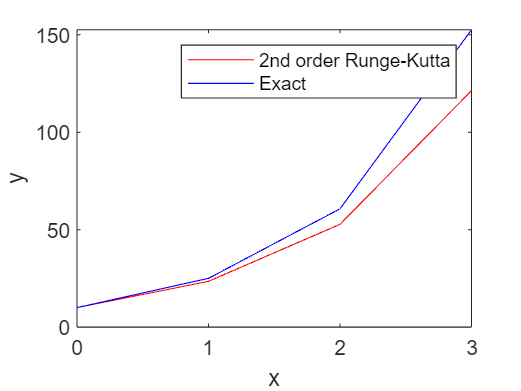



for i=1:length(x)-1
    k1=m(x(i),y(i));
    k2=m(x(i)+q*h,y(i)+q*k1*h);
    y(i+1)=y(i)+(a1*k1+a2*k2)*h;

    err(i+1)=abs((yexact(x(i+1))-y(i+1))/yexact(x(i+1)))*100;
end


plot(x,y,'r')
hold on
plot(x,yexact(x),'b')
hold off
xlabel("x")
ylabel("y")
legend("2nd order Runge-Kutta","Exact")